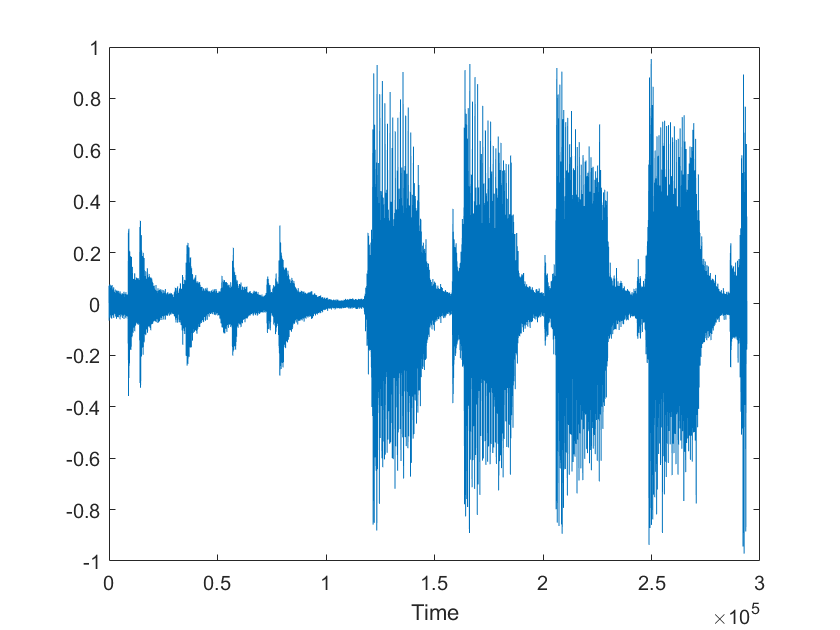

clear;
clf;

f='trans.wav';         %file to inspect          
[x,sr]=audioread(f);   %reads file
figure(1)
plot(x)                %plots waveform
xlabel('Time');
ylabel('');

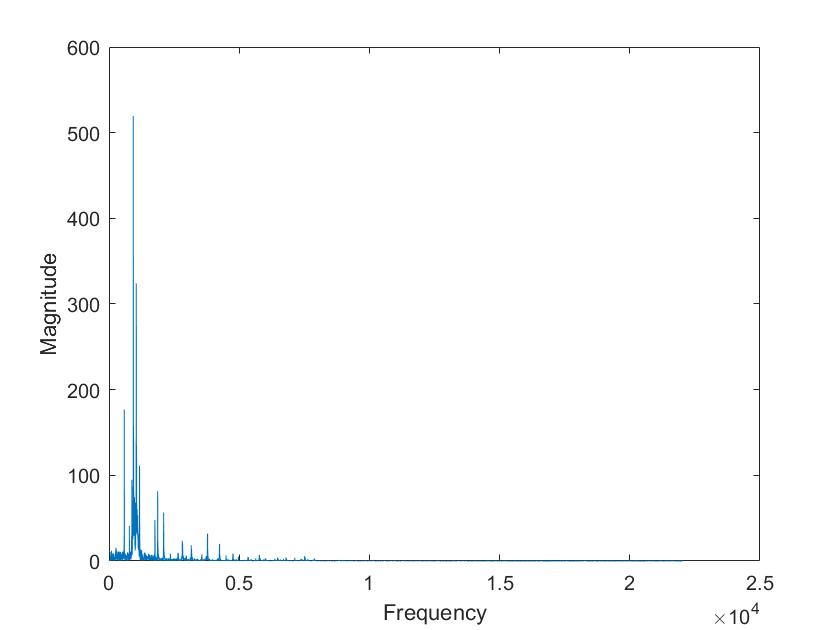


Ts=1/sr;               %             
N=2^15;                %Number of Samples
x=x(1:N)';             %Limits to sample size   
time=Ts*(0:length(x)-1);       
figure(2)
magx=abs(fft(x));      %FFT magnitude      
ssf=(0:N/2-1)/(Ts*N);       
plot(ssf,magx(1:N/2))
xlabel('Frequency');
ylabel('Magnitude');


clear sound;